clc;
clear all;
addpath('../utils')

This script showcases the genOFDM function, on which the Starlink-specific functions are based on. In this playground, you can view a spectrogram, a power plot (PSD or Power vs time), and view a constellation plot of the sub-carrier data.

%--------------------------------------%
%----------------Option----------------%
%--------------------------------------%
specPlot_en = 1;
pwrPlot_en = 1;
constPlot_en = 1;

After choosing how many consecutive OFDM symbols will be generated you can customize the signal.

%--------------------------------------%
%----------------Params----------------%
%--------------------------------------%
NFFT = 2^10; % # of FFT points for spectrogram, if too many points, it is reduced later
Nsym = 298;

You can choose an SNR, a receiver sampling rate Fsr, a receiver center frequency, a CFO (beta), the modulation index, the modulation scheme, the number of subcarriers (N), the cyclic prefix length (Ng), and the channel center, and channel bandwidth. Also, a toggle to enable the gutter (4 center sub-carriers have no power in Starlink).

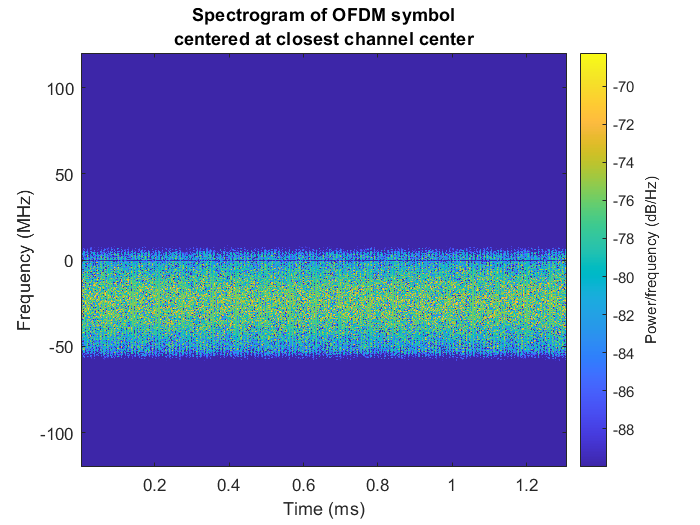

%--------------------------------------%
%---------OFDM Input params------------%
%--------------------------------------%
% Signal to noise ratio, in dB
s.SNRdB = nan();
% Receiver sample rate.  If this is less than Fs, then the signal is filtered
% before resampling to prevent aliasing.  Set Fsr to Fs to skip resampling.
s.Fsr = 62.5e6;
% Receiver center frequency, in Hz
s.Fcr = getClosestFch(11.775e9)-25e6;
s.beta = 0; 
s.Midx = 4;
s.type = 'QAM';
s.N = 1024;
s.Ng = 32;
s.Nsym = Nsym;
s.Fc = getClosestFch(11.775e9);
s.Fs = 240e6;
s.gutter = 1;
%--------------------------------------%
%---------Generate Signal -------------%
%--------------------------------------%

y = genOFDM(s);

%--------------------------------------%
%---------Spectrogram -----------------%
%--------------------------------------%

if(specPlot_en)
    t = sprintf('Spectrogram of OFDM symbol');
    Stitle = {t,'centered at closest channel center'};
    F = 240e6/1024;
    chIdx = round((s.Fcr/1e9 - 10.7 - F/2/1e9)/0.25 + 0.5);
    Fcii = (10.7e9 + F/2 + 250e6*(chIdx - 0.5));
    plotSpec(y,0,0,s.Fcr,s.Fsr,Fcii,s.Fs,NFFT,Stitle)
end

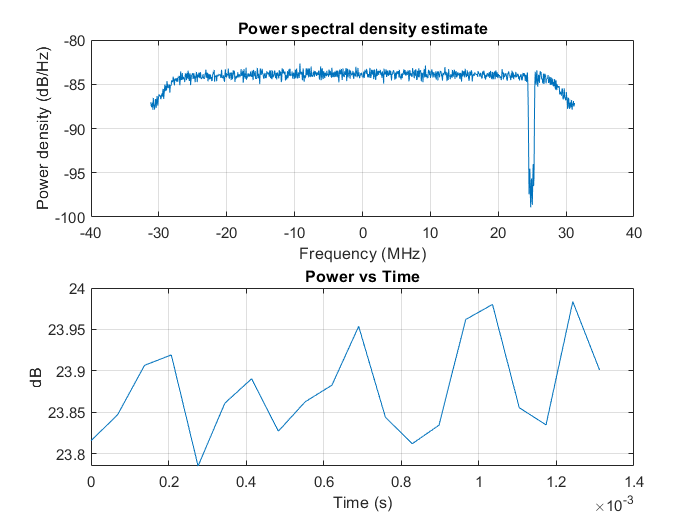

Press any key to start constellation plotting loop...




%--------------------------------------%
%---------Power Plots -----------------%
%--------------------------------------%

if (pwrPlot_en)
    Stitle = {'Spectrogram of starlink signal','centered at closest channel center'};
    plotPwr(y,20,0,length(y)/s.Fsr,s.Fsr,NFFT)
end

%--------------------------------------%
%---------Const Plots -----------------%
%--------------------------------------%
sc_mag_threshold = 0.95; % between 0 and 1;

if (constPlot_en)
    
    % resample and center to channel
    if (s.Fsr ~= 240e6)
        tVec = [0:length(y)-1]'/s.Fsr;
        [y,tVec] = resample(y,tVec,240e6);
    end
    if (getClosestFch(s.Fcr) - s.Fcr ~= 0)
        tVec = [0:length(y)-1]'/(240e6); 
        Fshift =  getClosestFch(s.Fcr) - s.Fcr;
        y = y.*exp(-j*2*pi*Fshift*tVec);
    end
    % zero pad
    yVec = [y; zeros((1056)*ceil(length(y)/(1056)) - length(y),1)];
    % remove CP
    y = reshape(yVec,1056,[]);
    y = y(32+1:end,:);
    % take FFT
    Y = 1/sqrt(1024).*fft(y);
    % find good subchannels
    idx = find(abs(Y)/max(abs(Y)) > sc_mag_threshold);
    % set gutter values to nan()
    Y(1:2,:) = nan();
    Y(end-1:end,:) = nan();
    [l,w] = size(Y);
    fprintf("Press any key to start constellation plotting loop...\n")
    pause;
    figure()
    for ii = 1:w
        plot(Y(idx,ii),"*");
        pause(1)
    end
    
end